# Sample 12-3

## 画像復元

合成モデル

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image restoraton

Synthesis model

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### パラメータ設定

(Parameter settings)

- sgm: ノイズ標準偏差 $\sigma_w$ (Standard deviation of noise)

- nlevels: ウェーブレット段数 (Wavelet levels)

% Parameter settings
isaprxleft = true;
lambda = 10^-0.1

lambda = 0.7943

gamma = 10^0.3

gamma = 1.9953

sgmuint8 = 10; 
sgm = sgmuint8/255;
nlevels = 3; 
niters = 80;

## 画像の読込

(Read image)

u = rgb2gray(im2double(imread('./data/lena.png')));

## 観測画像

(Observation image)

- 
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


- 
$$\mathbf{u}=\mathbf{Ds}$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


% Definition of measurment process
psf = fspecial('motion',21,11);
measureproc = @(x) imfilter(x,psf,'conv','circular');
% Adjoint process of the measurment process
measureadjp = @(x) imfilter(x,psf,'corr','circular');
% Simulation of AWGN
v = imnoise(measureproc(u),'gaussian',0,sgm^2);

### 非間引きハールDWT

(Undecimated Haar DWT)

import msip.udhaarwtdec2
import msip.udhaarwtrec2

#### 完全再構成の確認 (Checki the perfect reconstruction)

非間引きハールDWTはパーセバルタイト性 (The undecimated DWT satisfies the Parseval tight property,)

        
$$\mathbf{DD}^T=\mathbf{I}$$


を満たすため， $\mathbf{D}$ の転置システムは完全再構成分析システムとなり得る．(and thus Its transposition system can be a PR analysis system.)

[coefs,scales] = udhaarwtdec2(v,nlevels);
r = udhaarwtrec2(coefs,scales);
assert(norm(v-r,"fro")^2/numel(v)<1e-18,'Perfect reconstruction is violated.')

合成辞書と転置辞書の定義 (Definition of synthesis dictionary  and its adjoint)

% Definiton of dictionay and its adjoint
adjdic = @(x) udhaarwtdec2(x,nlevels); % D
syndic = @(x) udhaarwtrec2(x,scales);  % D.'

### 近接勾配法

(Proximal gradient method)

#### 問題設定 (Problem setting)

         
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}}\frac{1}{2}\|\mathbf{v}-\mathbf{PDs}\|_2^2+\lambda\|\mathbf{s}\|_1$$


#### アルゴリズム (Algorithm)

- Initialization: $\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathrm{prox}_{\gamma g}\left( \mathbf{s}^{(t)}-\gamma\nabla_\mathbf{s}f(\mathbf{s}^{(t)})\right)$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

ただし，(where)

- 
$$\nabla_\mathbf{s}f(\mathbf{s})=\mathbf{D}^T\mathbf{P}^T(\mathbf{PDs}-\mathbf{v})$$


- 
$$\mathrm{prox}_{\gamma\lambda\|\cdot\|_{1}}(\mathbf{s})=\mathcal{T}_{\gamma\lambda}(\mathbf{s})=\mathrm{sign}(\mathbf{s})\odot\max(\mathrm{abs}(\mathbf{s})-\gamma\lambda\mathbf{1},\mathbf{0})$$


ソフト閾値処理 (Soft-thresholding)

softthresh = @(x,t) sign(x).*max(abs(x)-t,0);

初期化 (Initialization)

[coefs,scales] = udhaarwtdec2(v,nlevels);
sp = coefs;

近接勾配降下 (Proximal gradient descent)

- $\gamma<2/\beta$: Step size

- $\beta$: Lipschitz constant of $\nabla f$, where $\beta = (\sigma_{\mathrm{max}}(\mathbf{PD}))^2$

beta = max(abs(fftn(psf,2.^nextpow2(size(v)))),[],'all');
assert(gamma < 2/beta,'Step size condition is violated.')
if isaprxleft
    mask = ones(size(coefs));
    mask(1:prod(scales(1,:))) = 0;
    lambda = lambda * mask;
end
for idx=0:niters-1
    % Proximal gradient descent
    sg = adjdic(measureadjp(measureproc(syndic(sp))-v));
    sc = softthresh(sp-gamma*sg,gamma*lambda);
    % Update
    sp = sc;
end

### 復元画像

(Restored image)

r = syndic(sc);

### 画像表示

(Image show)

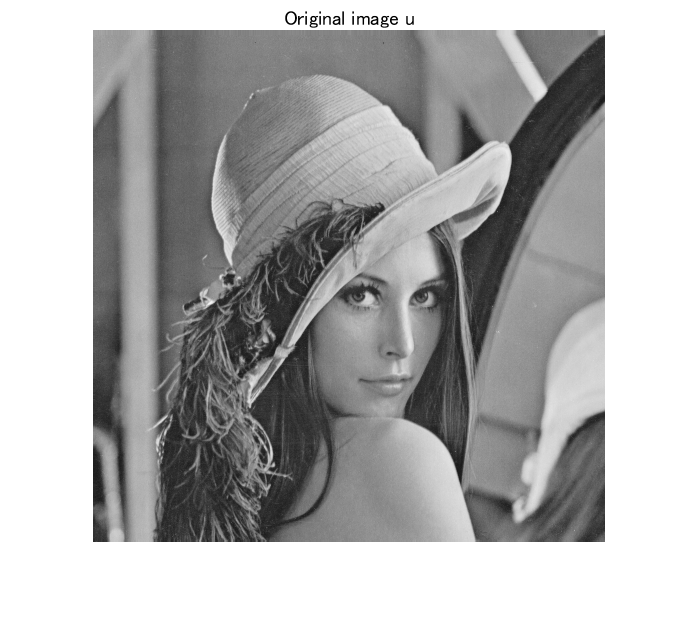

figure(1)
imshow(u);
title('Original image u')

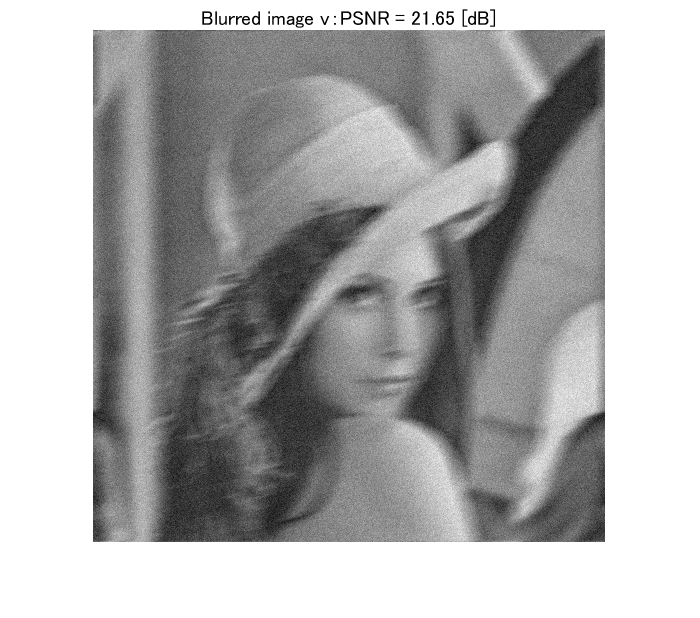

figure(2)
imshow(v)
title(sprintf('Blurred image v：PSNR = %5.2f [dB]',psnr(u,v)))

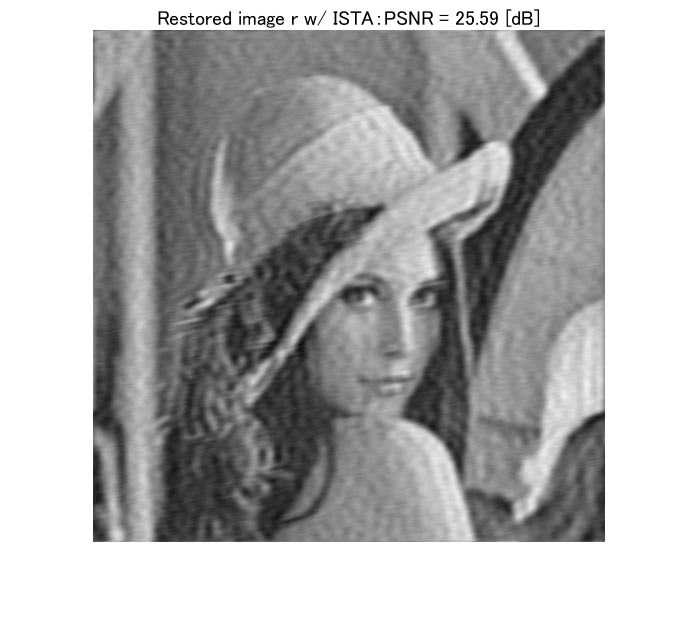

figure(3)
imshow(r)
title(sprintf('Restored image r w/ ISTA：PSNR = %5.2f [dB]',psnr(u,r)))

© Copyright, Shogo MURAMATSU, All rights reserved.